# Deep Learning Import and Export

**In this live script, I m going to show how to Import networks and network architectures from TensorFlow™-Keras, TensorFlow 2, Caffe, and the ONNX™ (Open Neural Network Exchange) model format. You can also export a trained Deep Learning Toolbox™ network to the ONNX model format.**

Load a pretrained SqueezeNet convolutional neural network.

net = squeezenet

net =   DAGNetwork with properties:

         Layers: [68×1 nnet.cnn.layer.Layer]
    Connections: [75×2 table]
     InputNames: {'data'}
    OutputNames: {'ClassificationLayer_predictions'}


Export the network as an ONNX format file in the current folder called `squeezenet.onnx`. You can later use this onnx model in Python by importing it in the Jupyter notebook. 

filename = 'squeezenet.onnx';
exportONNXNetwork(net,filename)

The inbuilt Keras network of h5 format is called and is imported using the **importKerasNetwork** function. 

This is a directed acyclic graph convolutional neural network trained on the digits data.

modelfile = 'digitsDAGnet.h5';
classNames = {'0','1','2','3','4','5','6','7','8','9'};

net = importKerasNetwork(modelfile,'Classes',classNames)

net =   DAGNetwork with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [13×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_activation_1'}


Plot the Network Architecture

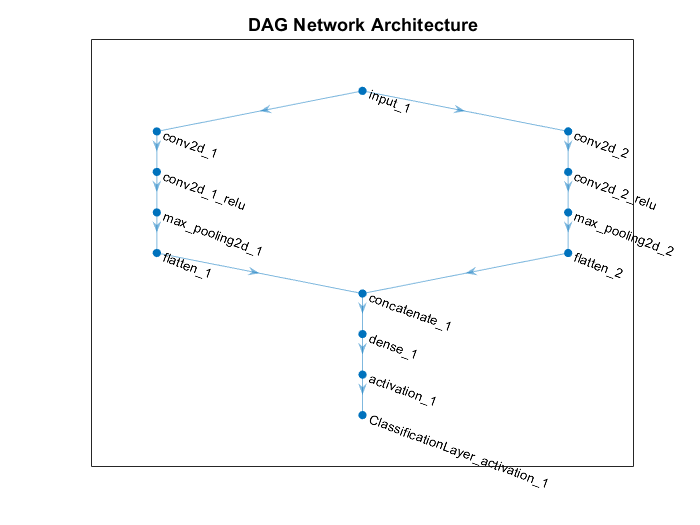

plot(net)
title('DAG Network Architecture')